# 10.21 - Linear Regression Ch 14

## Problem 14.3

Given the data, find the mean mode range std dev var, coeff of var. 

Make a histogram using range 28 to 34 w/ increments of 0.4

clc; clear; clear all;
A = [29.65 28.55 28.65 30.15 29.35 29.75 29.25 ...
    30.65 28.15 29.85 29.05 30.25 30.85 28.75 ...
     29.65 30.45 29.15 30.45 33.65 29.35 29.75 ... 
     31.25 29.45 30.15 29.65 30.55 29.65 29.25];

% Doesn't work as easily bc matlab does columns: 
% A = [29.65 28.55 28.65 30.15 29.35 29.75 29.25;
%       30.65 28.15 29.85 29.05 30.25 30.85 28.75;
%       29.65 30.45 29.15 30.45 33.65 29.35 29.75;
%       31.25 29.45 30.15 29.65 30.55 29.65 29.25]';


% goes column by column for bad way, full for good
mean_p = mean(A)

mean_p = 29.8321

med_p = median(A)

med_p = 29.6500

mod = mode(A)

mod = 29.6500

rang = range(A)

rang = 5.5000

rang_2 = max(A)-min(A)

rang_2 = 5.5000

stdDev = std(A)

stdDev = 1.0453

varA = var(A)

varA = 1.0926

cv = varA./mean_p*100 % percent

cv = 3.6626

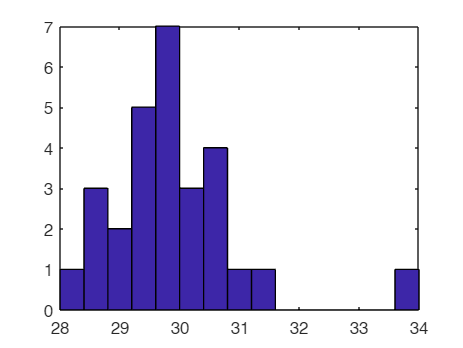


% goes whole array
%{
mean_wh = mean(mean_p')
med_wh = median(med_p')
mod_wh = mode(mod')
rang_wh = range(rang)
varA_wh= var(varA')
cv = varA_wh./mean_wh*100 % percent
%}

% histogram
binmids = [28.2:0.4:33.8];
hist(A,binmids)


% Also be able to do this in excel

## Problem 14.8

Linearize the model to estimate alph_4 and beta_4. Develop a plot of your fit along the data

y = a_4*x*exp(beta4*x)

clf;
x = [0.1 0.2 0.4 0.6 0.9 1.3 1.5 1.7 1.8];
y = [0.75 1.25 1.45 1.25 0.85 0.55 0.35 0.28 0.18];

help linregr

  linregr: linear regression curve fitting
  [a, r2] = linregr(x,y): Least squares fit of straight
  line to data by solving the normal equations
  input:
  x = independent variable
  y = dependent variable
  output:
  a = vector of slope, a(1), and intercept, a(2)
  r2 = coefficient of determination



% WRONG: have to transform first
% [a, r2] = linregr(x,y)

% linearize ****
% ln(y/x)=ln(alph_4)+beta4(x)
ln_yx = log(y./x); % natural logarithm ****
help log

 log    Natural logarithm.
    log(X) is the natural logarithm of the elements of X.
    Complex results are produced if X is not positive.
 
    See also log1p, log2, log10, exp, logm, reallog.

    Documentation for log
    Other uses of log



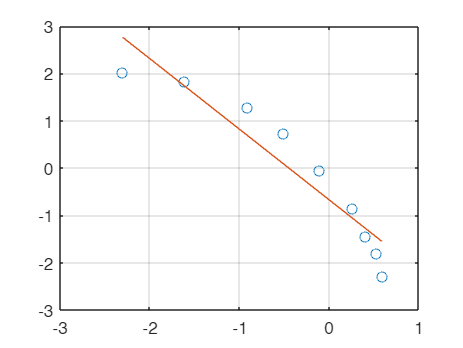

a =    -1.4936   -0.6748


r2 = 0.8903

[a, r2] = linregr(log(x),ln_yx)

% much better fit
alph = exp(a(2)) % a(2) = alpha!!!!!!

alph = 0.5092

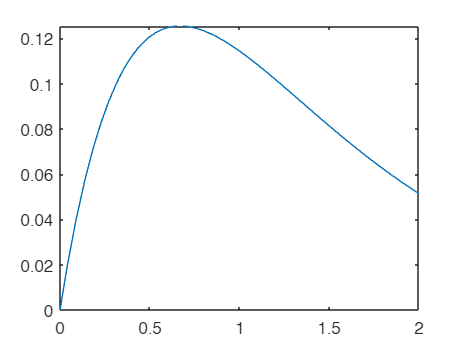

beta = a(1);
y_fit = @(x) alph*x.*exp(beta*x);
fplot(y_fit, [0 2])
hold off;


% Troy's approach
subplot(3,1,1);
hold on
plot(x,y,'o')
title('y versus x')
% RESULTS from lin reg of plot 2, with tools -> basic fitting -> linear on
% figure
% y = -2.473*x + 2.268
% so beta = -2.473
%    alph = exp(2.268)
alph = exp(2.268);
beta = -2.473;
y2 = alph*x.*exp(beta*x);
plot(x,y2)


subplot(3,1,2)
plot(x,log(y./x),'o')
subplot(3,1,3);
[a, r2] = linregr(x,ln_yx)

a =    -2.4733    2.2682


r2 = 0.9974


subplot(3,1,1);
%plot(x, a(1)*x.*exp(a(2)*x));
hold off;

% polyfit method
p = polyfit(log(x),log(y./x),1); % Oh wait, this is polynomial
y = polyval(p,log(x)) % this isn't as good as the expoential fit

y =     2.7643    1.7290    0.6937    0.0881   -0.5175   -1.0667   -1.2804   -1.4674   -1.5527


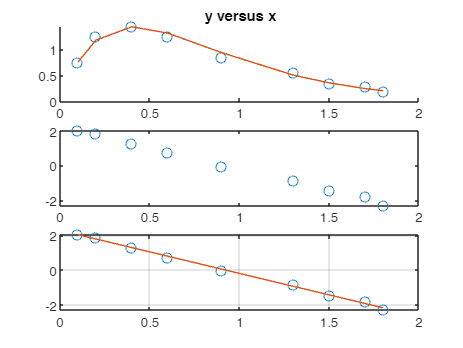

hold off;

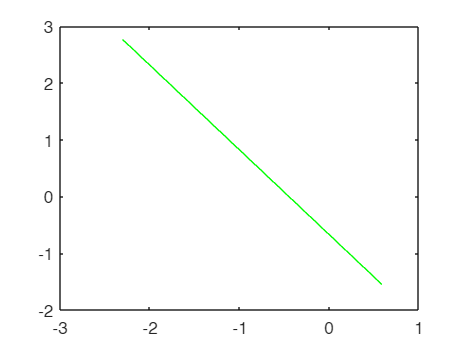

figure;
plot(log(x),y,'g')

y15 = polyval(p,1.5) % value of y at log(x) = 45

y15 = -2.9152

y_true = 1.5*exp(y15)

y_true = 0.0813